## 1.Signals and Systems

### 1.1 House keeping routine

% clear all variables in workspace
clear
 
% close any open figure windows (plots/graphs)
close all

### 1.2 signals in MATLAB: create a column vector *d*, using zeros(r,c)

freq = 3;
d = zeros(2*freq+1, 1);
d(2*freq+1) = 1;
fprintf('after assign d(7) = 1:');
d  % or check workspace variables
d(1) = (1/1i)^(2*freq);
fprintf('After assign d(7) and d(1):')
d

#### 1.3 Signal Operation

#### 1.3.1 Phase shifting, or time delay

•Phase shift is basically ***time delay or advance*** of a waveform…

•… but measured with respect to the period of the waveform, which is 360^0  or 2π radians

•Equation x(t)=A sin (ωt+ φ)

•Radian frequency ωradians/second

•ω=2πf,  where f(or N) is in Hertz or cycles/second

freq = 20;          % in Hz
w = 2*pi *freq;     % in rad./second

T = 1 / freq;       % in Sec.
k = 3;              % how many periods
t = linspace(0,k*T,k*20);% 20 samples / period

x1 = sin(w*t);
x2 = sin(w*t - pi/2);
subplot(2,1,1)
plot(t,x1,t,x2,'o')
title('--no shifting & \pi/2 delay--')
grid on
subplot(2,1,2)
stem(x2, 'b');
title('--\pi/2 delay--')

#### 1.3.2 Integrating and differentiating

% discreted approach
% dt = (k*T)/(k*20)
% y1 = dt*cumsum(x1);
% 
% figure
% subplot(2,1,1)
%     plot(t,x1,LineWidth=1)
%     grid on
%     title('-- sin(\omega*t)--')
% subplot(2,1,2)
%     plot(t,y1,LineWidth=2)
%     grid on
%     title('--integration operation to sin(\omega*t)--')

% symbol math approach
syms t
f  = sin(t)

$$f = \sin\left(t\right)$$

f1 = sin(t) + 0.2

$$f1 = \sin\left(t\right)+\frac{1}{5}$$

f2  = int(f1,t)

$$f2 = \frac{t}{5}-\cos\left(t\right)$$

var = vpa(f2)

$$var = 0.2\,t-1.0\,\cos\left(t\right)$$

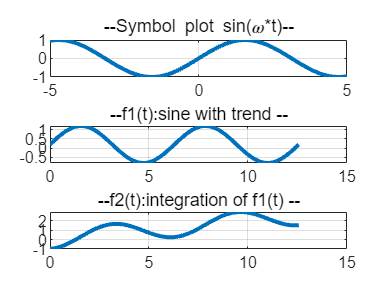


figure
subplot(3,1,1)
    fplot(f,LineWidth=2)
    grid on
    title('--Symbol plot sin(\omega*t)--')
 
td  = linspace(0,4*pi,100);
f1d = double(subs(f1,t,td));
subplot(3,1,2)
    plot(td,f1d,LineWidth=2)
    grid on
    title('--f1(t):sine with trend --')

%td  = linspace(0,4*pi,100);
f2d = double(subs(f2,t,td));
subplot(3,1,3)
    plot(td,f2d,LineWidth=2)
    grid on
    title('--f2(t):integration of f1(t) --')

[Next Step Suggestions for Symbolic Workflows in Live Editor - MATLAB & Simulink Example - MathWorks 中国](https://ww2.mathworks.cn/help/releases/R2023a/symbolic/next-step-suggestions-for-symbolic-workflows.html)